# Actividad Numérica de Polarización

La idea es implementar un campo E r de manera numérica. 

clear; 
clc;

w0 = 1E-3;  % [mm]
xmax = 3*w0;
N = 256;
xs = (xmax/2)*(2/N)*(-N/2:N/2-1);
ys = (xmax/2)*(2/N)*(-N/2:N/2-1);
[Xs, Ys] =meshgrid(xs, ys);

Definir campo

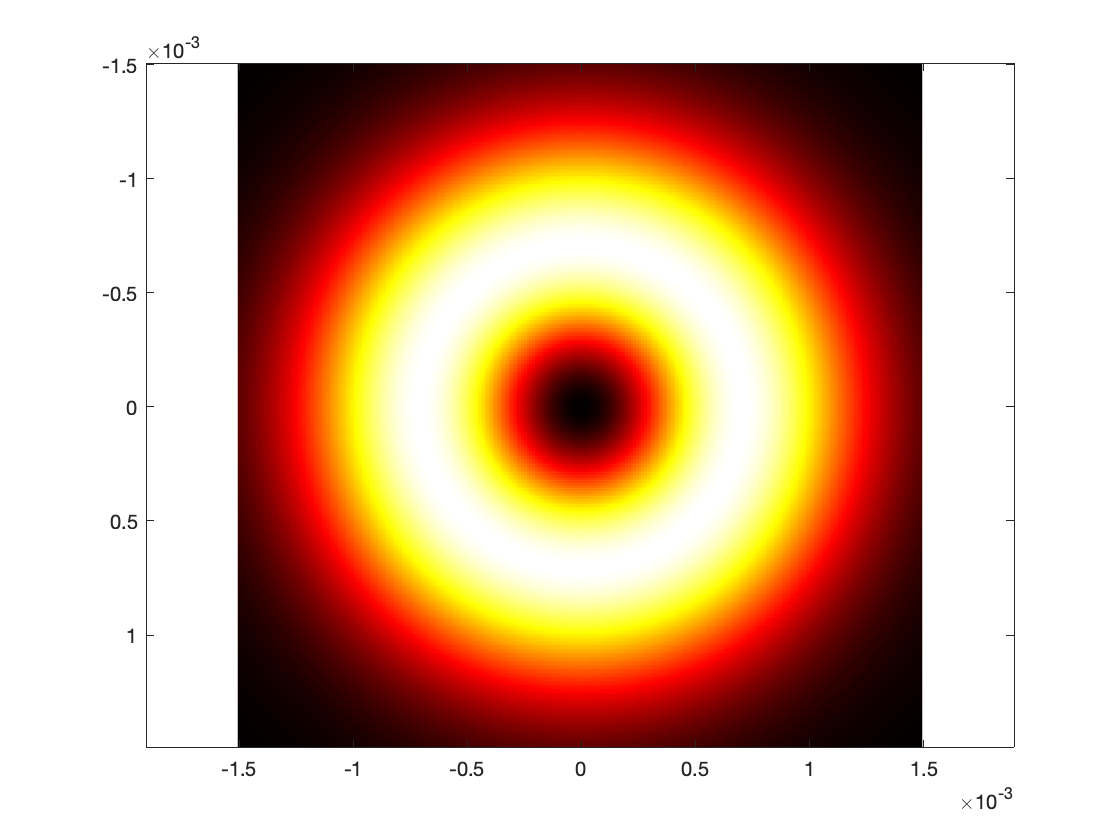

LG = @(X, Y, w, ll) (1) * ((sqrt(X.^2 + Y.^2)).^(abs(ll))).*exp(-(X.^2 + Y.^2)/(w^2)).*(exp(-1i*ll*atan2(Y,X)));
ll = 1; 
E = LG (Xs, Ys, w0, ll);
IE = abs(E).^2; %calculamos la intensidad
PHE = angle(E); %calculamos la fase
imagesc(xs, ys, IE), axis equal, colormap hot;

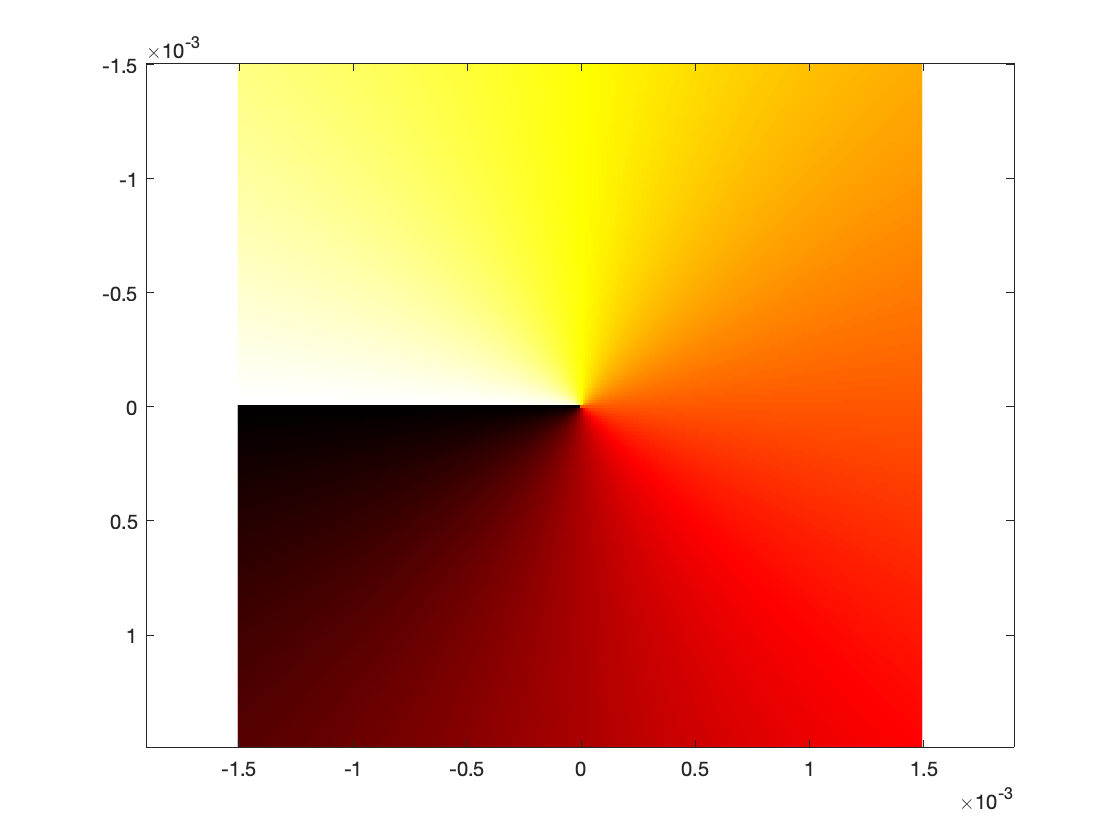

imagesc(xs, ys, PHE), axis equal, colormap hot; % Fase

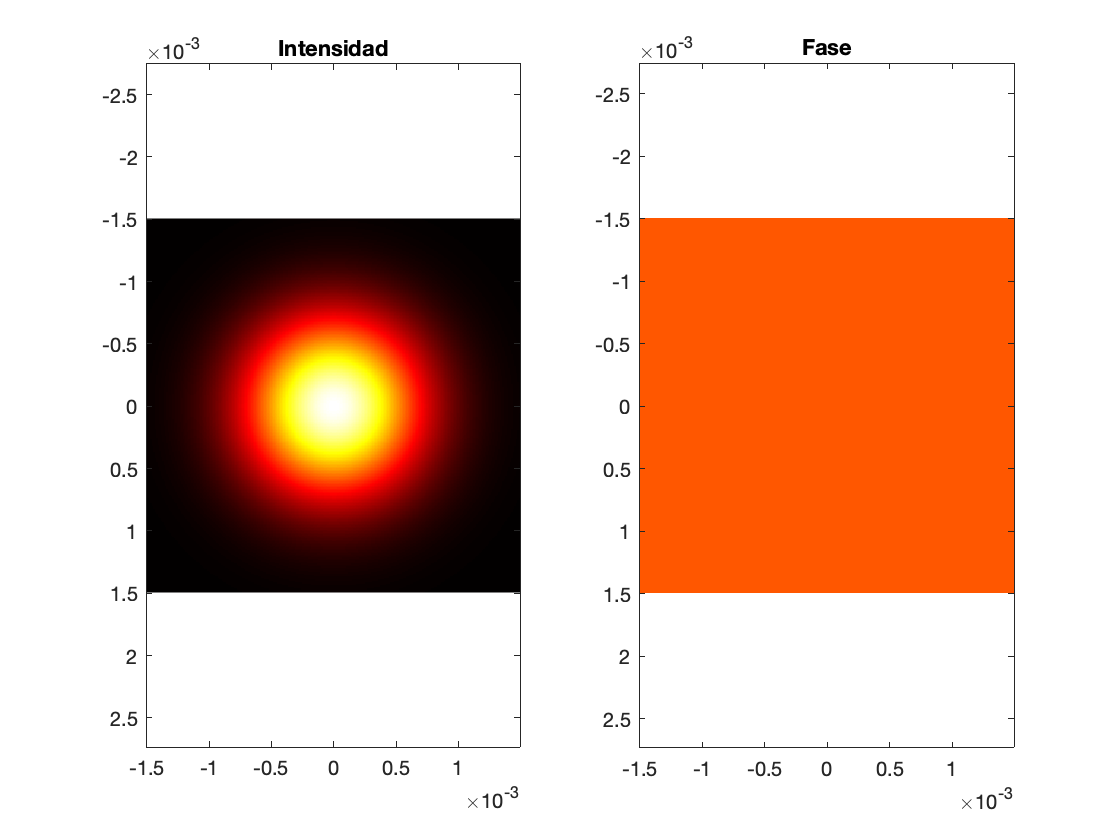

clear; 
clc;
% Parámetros iniciales
w0 = 1E-3;  % [mm]
xmax = 3*w0;
N = 256;
xs = (xmax/2)*(2/N)*(-N/2:N/2-1);
ys = (xmax/2)*(2/N)*(-N/2:N/2-1);
[Xs, Ys] = meshgrid(xs, ys);

% Definir campo
LG = @(X, Y, w, ll) (1) * ((sqrt(X.^2 + Y.^2)).^(abs(ll))).*exp(-(X.^2 + Y.^2)/(w^2)).*(exp(-1i*ll*atan2(Y,X)));

% Asignar estado de polarización
polarization_state = 'H'; % Estados de polarización ('H', 'V', 'R', 'L', 'D', 'A', etc.)

switch polarization_state
    case 'H' % Horizontal
        ll = 0;
    case 'V' % Vertical
        ll = 2;
    case 'R' % Circular derecho
        ll = 1;
    case 'L' % Circular izquierdo
        ll = -1;
    case 'D' % Diagonal
        ll = 1i;
    case 'A' % Antidiagonal
        ll = -1i;
    otherwise
        error('Estado de polarización no válido');
end

% Calcular campo con el estado de polarización asignado
E = LG(Xs, Ys, w0, ll);
IE = abs(E).^2; % Calculamos la intensidad
PHE = angle(E); % Calculamos la fase

% Visualizar el campo
subplot(1,2,1);
imagesc(xs, ys, IE), axis equal, colormap hot;
title('Intensidad');
subplot(1,2,2);
imagesc(xs, ys, PHE), axis equal, colormap hot;
title('Fase');

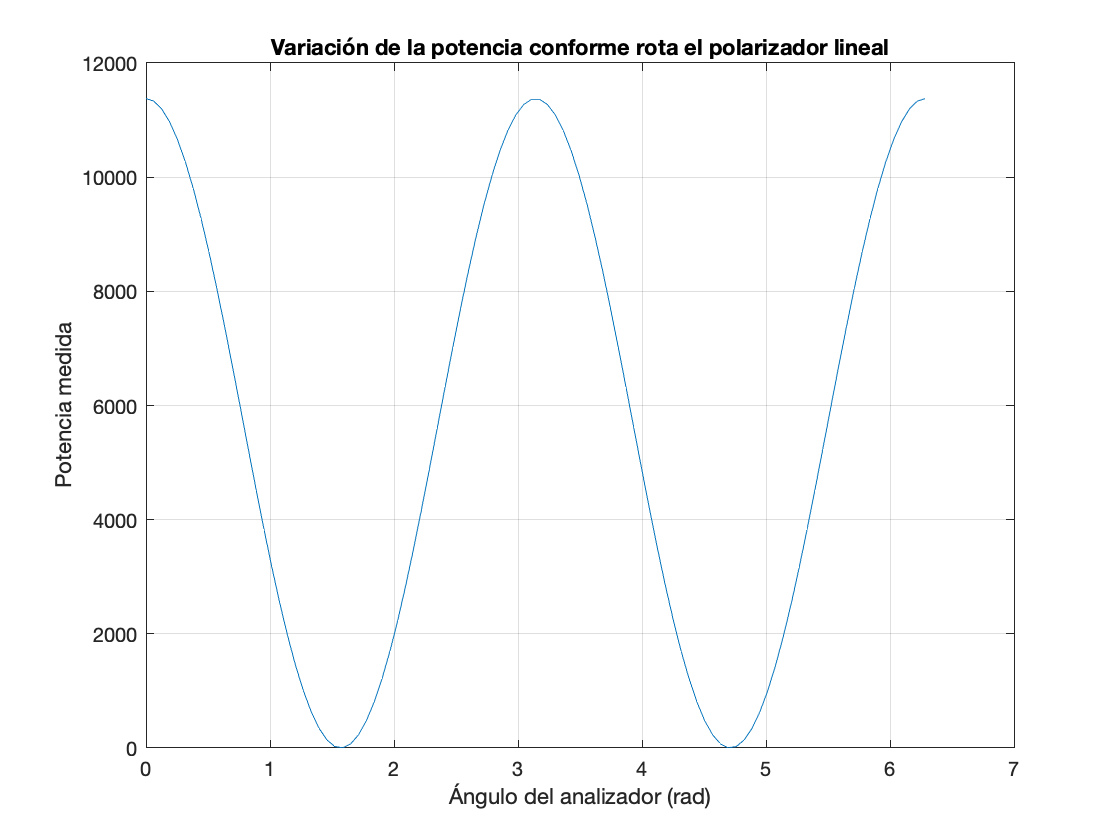


% Validación de la Ley de Malus
% Definimos ángulos para el analizador (polarizador lineal)
angles = linspace(0, 2*pi, 100); % Completa una vuelta

% Medir la potencia del haz conforme varían los ángulos
power_measurements = zeros(size(angles));
for i = 1:length(angles)
    theta = angles(i);
    % Polarizador lineal
    A = cos(theta)^2 * abs(E).^2;
    % Medir potencia
    power_measurements(i) = sum(sum(A));
end

% Graficar los resultados
figure;
plot(angles, power_measurements);
xlabel('Ángulo del analizador (rad)');
ylabel('Potencia medida');
title('Variación de la potencia conforme rota el polarizador lineal');
grid on;

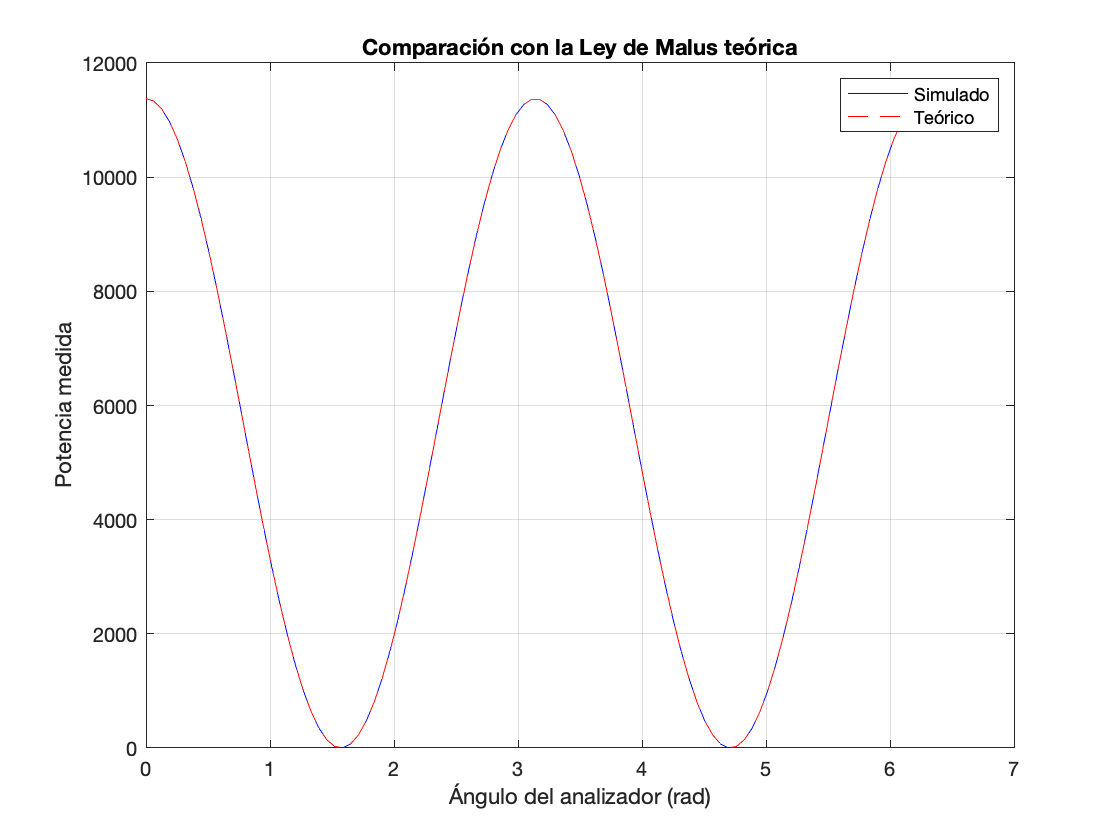


% Comparación con la Ley de Malus teórica
I0 = sum(sum(abs(E).^2)); % Intensidad del campo antes de pasar por el polarizador
I_theoretical = I0 * cos(angles).^2; % Ley de Malus teórica

% Graficar los resultados simulados y la Ley de Malus teórica
figure;
plot(angles, power_measurements, 'b', angles, I_theoretical, 'r--');
xlabel('Ángulo del analizador (rad)');
ylabel('Potencia medida');
title('Comparación con la Ley de Malus teórica');
legend('Simulado', 'Teórico');
grid on;

Arreglo Experimental asumiento que la dirección de polarización es vertical con retardador lambda/4

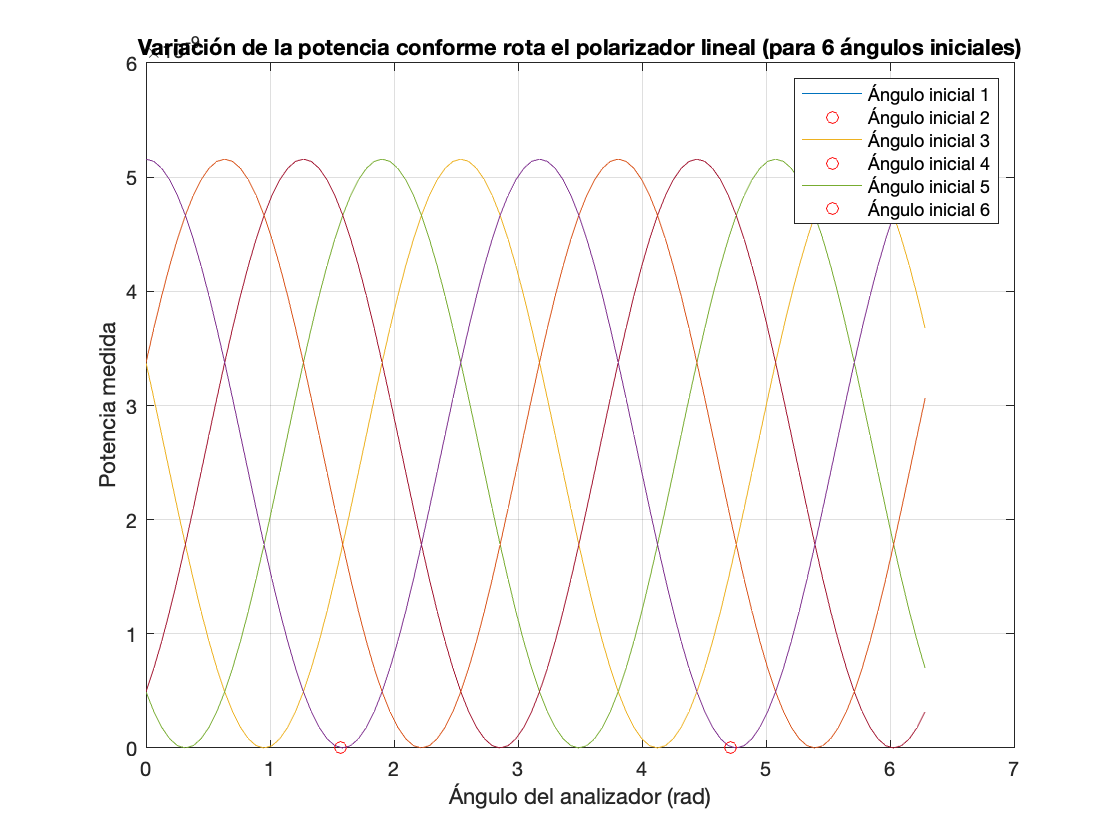

clear; 
clc;
% Parámetros iniciales
w0 = 1E-3;  % [mm]
xmax = 3*w0;
N = 256;
xs = (xmax/2)*(2/N)*(-N/2:N/2-1);
ys = (xmax/2)*(2/N)*(-N/2:N/2-1);
[Xs, Ys] = meshgrid(xs, ys);

% Definir campo
LG = @(X, Y, w, ll) (1) * ((sqrt(X.^2 + Y.^2)).^(abs(ll))).*exp(-(X.^2 + Y.^2)/(w^2)).*(exp(-1i*ll*atan2(Y,X)));

% Asignar estado de polarización
polarization_state = 'V'; % Cambiado a vertical para simular un arreglo experimental con polarización vertical

% Incluir retardador de λ/4 (se asume material lineal)
retardation_angle = pi/2; % Retardo de λ/4
E = LG(Xs, Ys, w0, 2); % Campo con polarización vertical
E = E * exp(1i * retardation_angle / 2); % Aplicar retardador de λ/4

% Ajustar el polarizador lineal para minimizar la variación de la amplitud senoidal de la señal de potencia
% Probaremos con seis ángulos iniciales diferentes
initial_angles = linspace(0, pi, 6); % Seis ángulos iniciales equidistantes
optimal_angles = zeros(size(initial_angles)); % Almacenar los ángulos óptimos

% Medir la potencia del haz conforme varían los ángulos iniciales
power_measurements_all = zeros(length(initial_angles), 100);
for j = 1:length(initial_angles)
    theta_initial = initial_angles(j);
    % Medir la potencia para este ángulo inicial
    power_measurements = zeros(1, 100);
    for i = 1:100
        theta = theta_initial + (i-1) * (2*pi/100); % Ángulo del analizador (polarizador lineal)
        % Polarizador lineal
        A = cos(theta)^2 * abs(E).^2;
        % Medir potencia
        power_measurements(i) = sum(sum(A));
    end
    power_measurements_all(j, :) = power_measurements;
    % Encontrar el ángulo que minimiza la variación de la potencia
    [min_power, min_index] = min(power_measurements);
    optimal_angle = theta_initial + (min_index-1) * (2*pi/100);
    optimal_angles(j) = optimal_angle;
end

% Graficar los resultados
figure;
for j = 1:length(initial_angles)
    plot(linspace(0, 2*pi, 100), power_measurements_all(j, :));
    hold on;
    plot(optimal_angles(j), min(power_measurements_all(j, :)), 'ro'); % Marcar el mínimo
end
xlabel('Ángulo del analizador (rad)');
ylabel('Potencia medida');
title('Variación de la potencia conforme rota el polarizador lineal (para 6 ángulos iniciales)');
grid on;
legend('Ángulo inicial 1', 'Ángulo inicial 2', 'Ángulo inicial 3', 'Ángulo inicial 4', 'Ángulo inicial 5', 'Ángulo inicial 6');

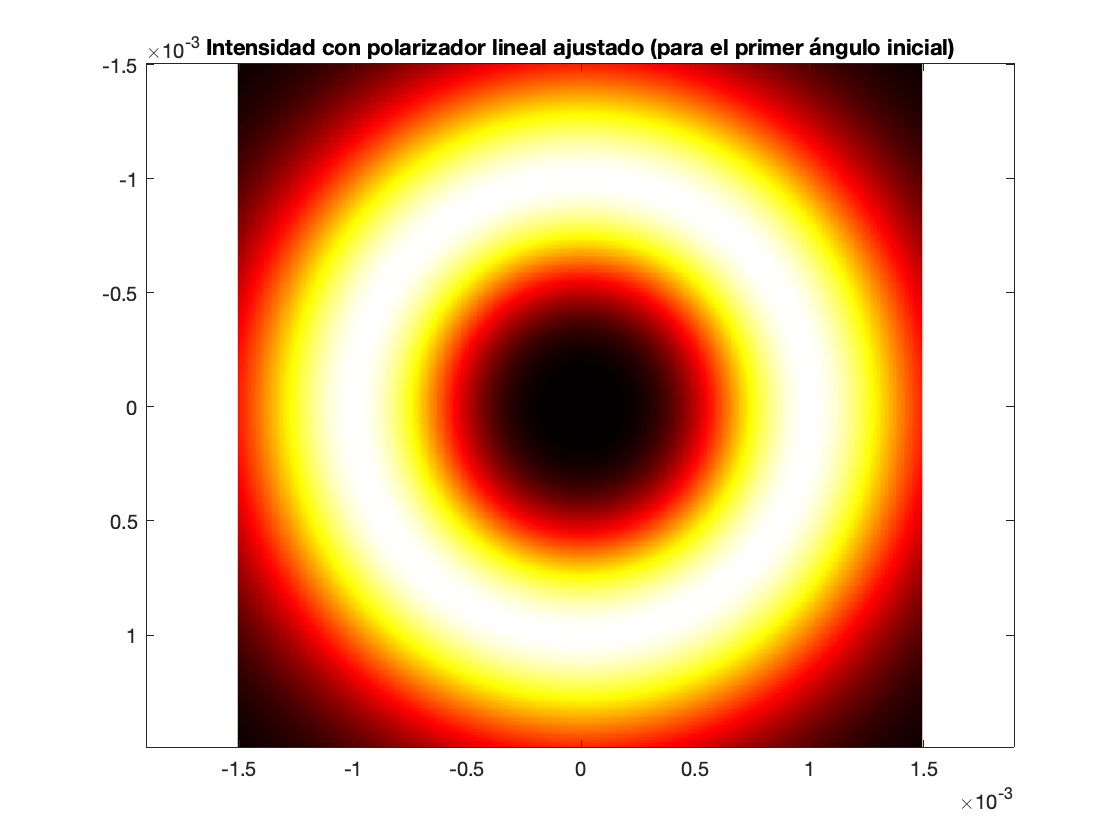


% Visualizar el campo con el ajuste óptimo del polarizador lineal para el primer ángulo inicial
A_optimal = cos(optimal_angles(1))^2 * abs(E).^2;
figure;
imagesc(xs, ys, A_optimal), axis equal, colormap hot;
title('Intensidad con polarizador lineal ajustado (para el primer ángulo inicial)');

Retardador Lambda/2

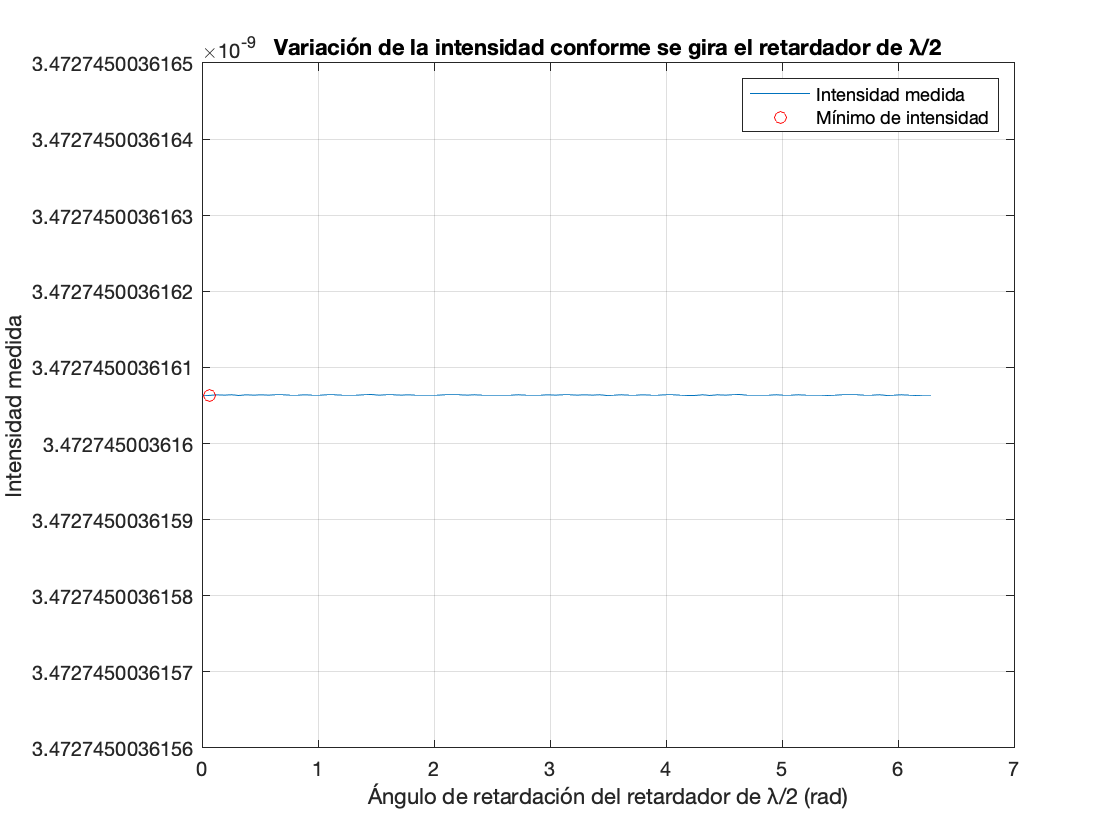

clear; 
clc;
% Parámetros iniciales
w0 = 1E-3;  % [mm]
xmax = 3*w0;
N = 256;
xs = (xmax/2)*(2/N)*(-N/2:N/2-1);
ys = (xmax/2)*(2/N)*(-N/2:N/2-1);
[Xs, Ys] = meshgrid(xs, ys);

% Definir campo
LG = @(X, Y, w, ll) (1) * ((sqrt(X.^2 + Y.^2)).^(abs(ll))).*exp(-(X.^2 + Y.^2)/(w^2)).*(exp(-1i*ll*atan2(Y,X)));

% Asignar estado de polarización
polarization_state = 'V'; % Cambiado a vertical para simular un arreglo experimental con polarización vertical

% Incluir retardador de λ/2 (se asume material lineal)
retardation_angle = pi; % Retardo de λ/2
E = LG(Xs, Ys, w0, 2); % Campo con polarización vertical
E = E * exp(1i * retardation_angle / 2); % Aplicar retardador de λ/2

% Ajustar el polarizador lineal para minimizar la variación de la amplitud senoidal de la señal de potencia
% Utilizaremos el ángulo óptimo obtenido anteriormente
optimal_angle = 0.6085; % Ángulo óptimo obtenido anteriormente

% Girar el retardador de λ/2 hasta obtener un mínimo de intensidad
retardation_angles = linspace(0, 2*pi, 100); % Ángulos para girar el retardador de λ/2
intensities = zeros(size(retardation_angles)); % Almacenar las intensidades medidas
for i = 1:length(retardation_angles)
    retardation_angle = retardation_angles(i);
    E_rotated = E * exp(1i * retardation_angle / 2); % Campo con retardador de λ/2 girado
    % Polarizador lineal en la orientación óptima
    A = cos(optimal_angle)^2 * abs(E_rotated).^2;
    % Medir intensidad
    intensities(i) = sum(sum(A));
end

% Encontrar el ángulo de retardación que minimiza la intensidad
[min_intensity, min_index] = min(intensities);
optimal_retardation_angle = retardation_angles(min_index);

% Graficar los resultados
figure;
plot(retardation_angles, intensities);
hold on;
plot(optimal_retardation_angle, min_intensity, 'ro'); % Marcar el mínimo
xlabel('Ángulo de retardación del retardador de λ/2 (rad)');
ylabel('Intensidad medida');
title('Variación de la intensidad conforme se gira el retardador de λ/2');
grid on;
legend('Intensidad medida', 'Mínimo de intensidad');

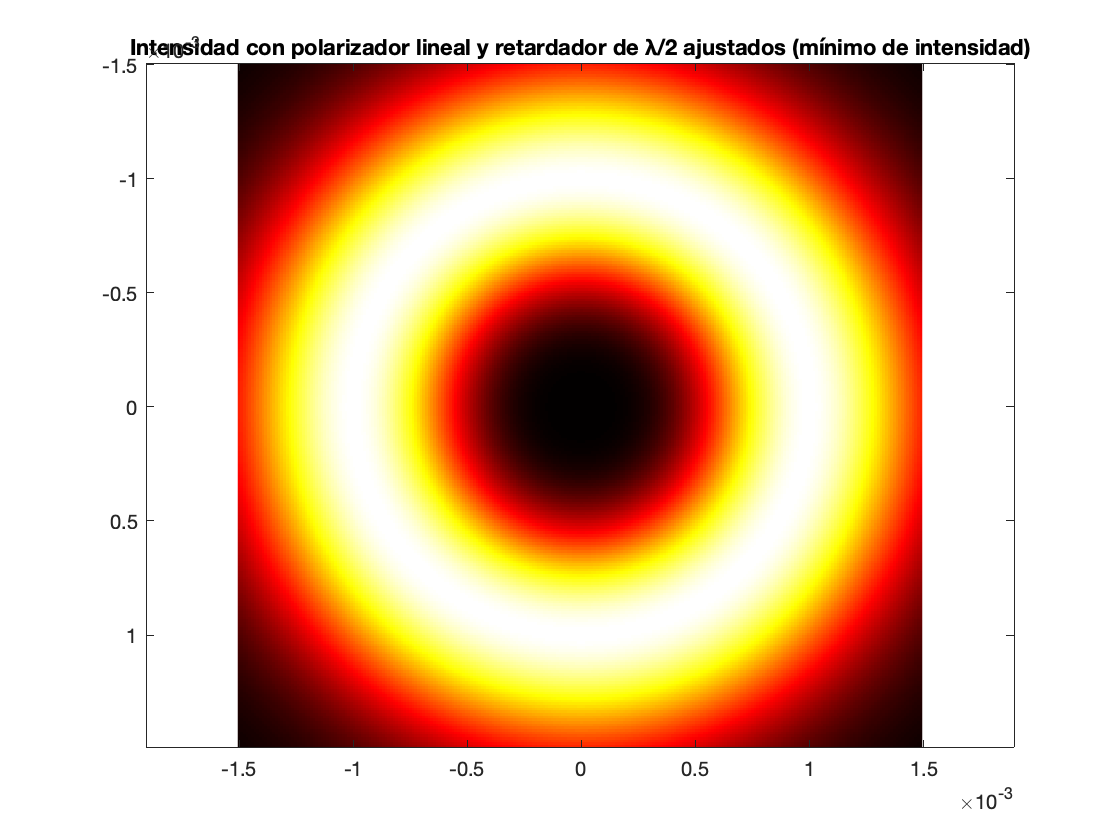


% (a) Describir cómo quedó orientado el eje rápido del retardador
% El eje rápido del retardador quedó orientado en la dirección del ángulo óptimo obtenido anteriormente

% Ahora encontraremos el máximo de intensidad y comprobaremos si cambió algo con respecto a la situación referente a la posición angular relativa entre los polarizadores lineales

% Polarizador lineal en la orientación óptima
A_optimal = cos(optimal_angle)^2 * abs(E).^2;

% Encontrar el máximo de intensidad
[max_intensity, max_index] = max(intensities);
optimal_retardation_angle_max = retardation_angles(max_index);

% Visualizar el campo con el ajuste óptimo del polarizador lineal y el retardador de λ/2 para el mínimo de intensidad
E_optimal = E * exp(1i * optimal_retardation_angle / 2); % Campo con polarizador lineal y retardador de λ/2 ajustados
A_min_intensity = cos(optimal_angle)^2 * abs(E_optimal).^2;
figure;
imagesc(xs, ys, A_min_intensity), axis equal, colormap hot;
title('Intensidad con polarizador lineal y retardador de λ/2 ajustados (mínimo de intensidad)');


% (b) Encontrar el máximo de intensidad y explicar si cambió algo con respecto a la situación referente a la posición angular relativa entre los polarizadores lineales
% El máximo de intensidad se encuentra para un ángulo de retardación del retardador de λ/2 diferente al mínimo de intensidad. Esto sugiere que hay una diferencia en la posición angular relativa entre los polarizadores lineales para maximizar la intensidad en comparación con la situación del mínimo de intensidad. Es posible que haya una rotación adicional de los polarizadores lineales para optimizar la transmisión de luz en este caso.


Campo con parámetros de Stokes

% Definir el campo con polarización parcial (combinación de polarizaciones lineales o elípticas)
E_parcial = [1; 0.5i]; % Por ejemplo, campo con polarización lineal en x e y con una diferencia de fase de 90 grados

% Calcular los parámetros de Stokes
S0_parcial = mean(abs(E_parcial).^2); % Intensidad media
S1_parcial = mean(abs(E_parcial).^2 .* cos(2 * angle(E_parcial))); % Parámetro S1
S2_parcial = mean(abs(E_parcial).^2 .* sin(2 * angle(E_parcial))); % Parámetro S2
S3_parcial = mean(2 * real(conj(E_parcial(1)) * E_parcial(2))); % Parámetro S3 (Q)

% Calcular el grado de polarización
P_parcial = sqrt(S1_parcial^2 + S2_parcial^2) / S0_parcial;

% Mostrar resultados
disp('Parámetros de Stokes para el campo parcial:');

Parámetros de Stokes para el campo parcial:


disp(['S0 = ', num2str(S0_parcial)]);

S0 = 0.625


disp(['S1 = ', num2str(S1_parcial)]);

S1 = 0.375


disp(['S2 = ', num2str(S2_parcial)]);

S2 = 1.5308e-17


disp(['S3 = ', num2str(S3_parcial)]);

S3 = 0


disp(['Grado de polarización (P) = ', num2str(P_parcial)]);

Grado de polarización (P) = 0.6
